clc
clear;
close all;

## 导入数据集

data1 = readtable('E:\研究生学习\模式识别\数据\wine\winequality-red.csv');

data2 = readtable('E:\研究生学习\模式识别\数据\wine\winequality-white.csv');

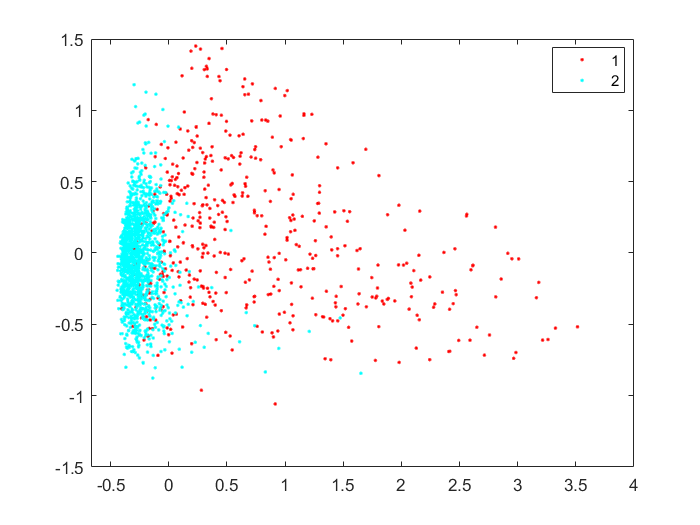

data_all1 = [data1;data2];

label1 = [ones(height(data1),1);2*ones(height(data2),1)];
s = randperm(height(data_all1));
label = label1(s(1:2000),:);
test_lab = label1(s(2001:4000),:);
% 先用pca
data_all1 = table2array(data_all1);
data_all = data_all1(s(1:2000),:);
test = data_all1(s(2001:4000),:);
data_all = zscore(data_all,0,2);
[coeff,scores,latent] = pca(data_all);
% 取前两个主轴
gscatter(scores(:,1),scores(:,2),label);

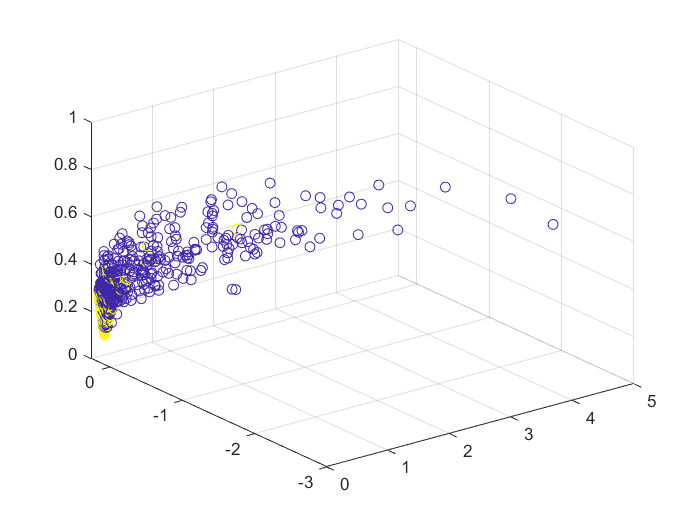

% 特征扩展feature mapping

z = [data_all(:,1).^2,sqrt(2).*data_all(:,1).*data_all(:,2),data_all(:,2).^2];
figure;
scatter3(z(:,1),z(:,2),z(:,3),[],label);

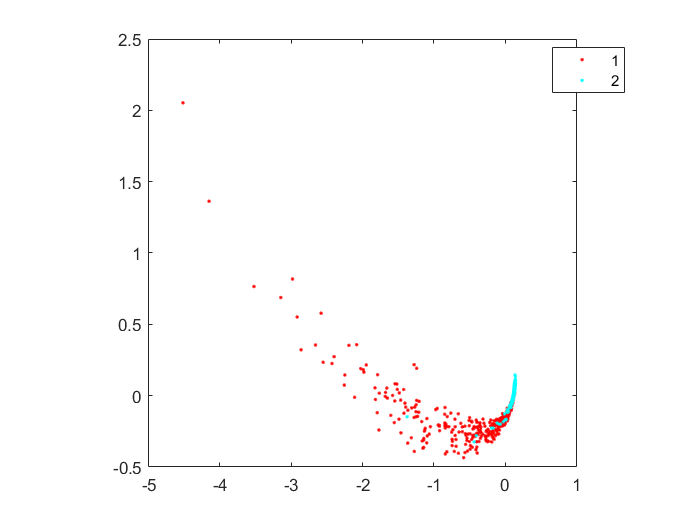

% PCA
[coeff,scores,latent] = pca(z);
gscatter(scores(:,1),scores(:,2),label);
axis square

%K2 = RBF_kernel(data_all,data_all,8);
%K2 = MLP_kernel(data_all,data_all,2);
%K2 = lin_kernel(data_all,data_all);
K2 = poly_kernel(data_all,data_all,0.8);

n = length(data_all);

E = ((1/n)*eye(n)-(1/n^2)*ones(n,n))*K2;

[U,lambda] = eig(E);

## 排序加计算所需参数

[lambda2,I] = sort(diag(lambda),'descend');
U = U(:,I);
% 计算贡献率
gxl = lambda2/sum(lambda2);
% 计算最终的Up
% 最终降到p维
p = 3;
for i = 1:p
    temp = U(:,1);
    Up(:,i) = temp/sqrt(temp'*K2*temp);
end

## SVM网络训练

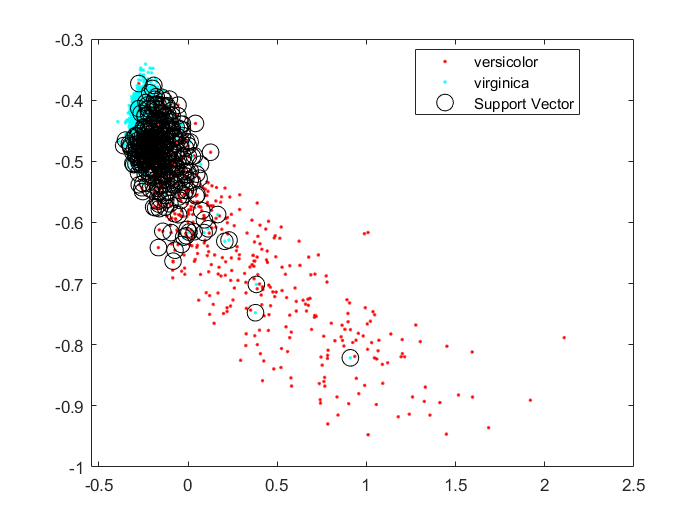

model = fitcsvm(data_all,label);
sv = model.SupportVectors;
figure
gscatter(data_all(:,1),data_all(:,2),label);
hold on
plot(sv(:,1),sv(:,2),'ko','MarkerSize',10)
legend('versicolor','virginica','Support Vector')
hold off

## 计算投影

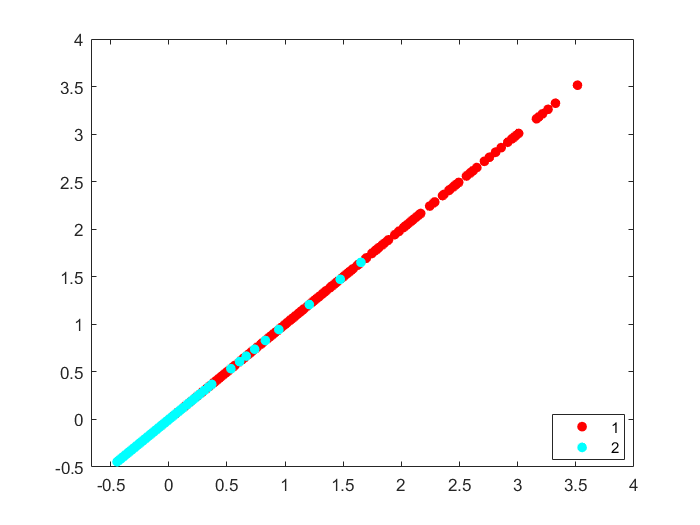

Y = (K2 - (1/n)*ones(n,n)*K2)*Up;
gscatter(Y(:,1),Y(:,2),label,[],[],20);

%scatter3(Y(:,1),Y(:,2),Y(:,3),[],label);
